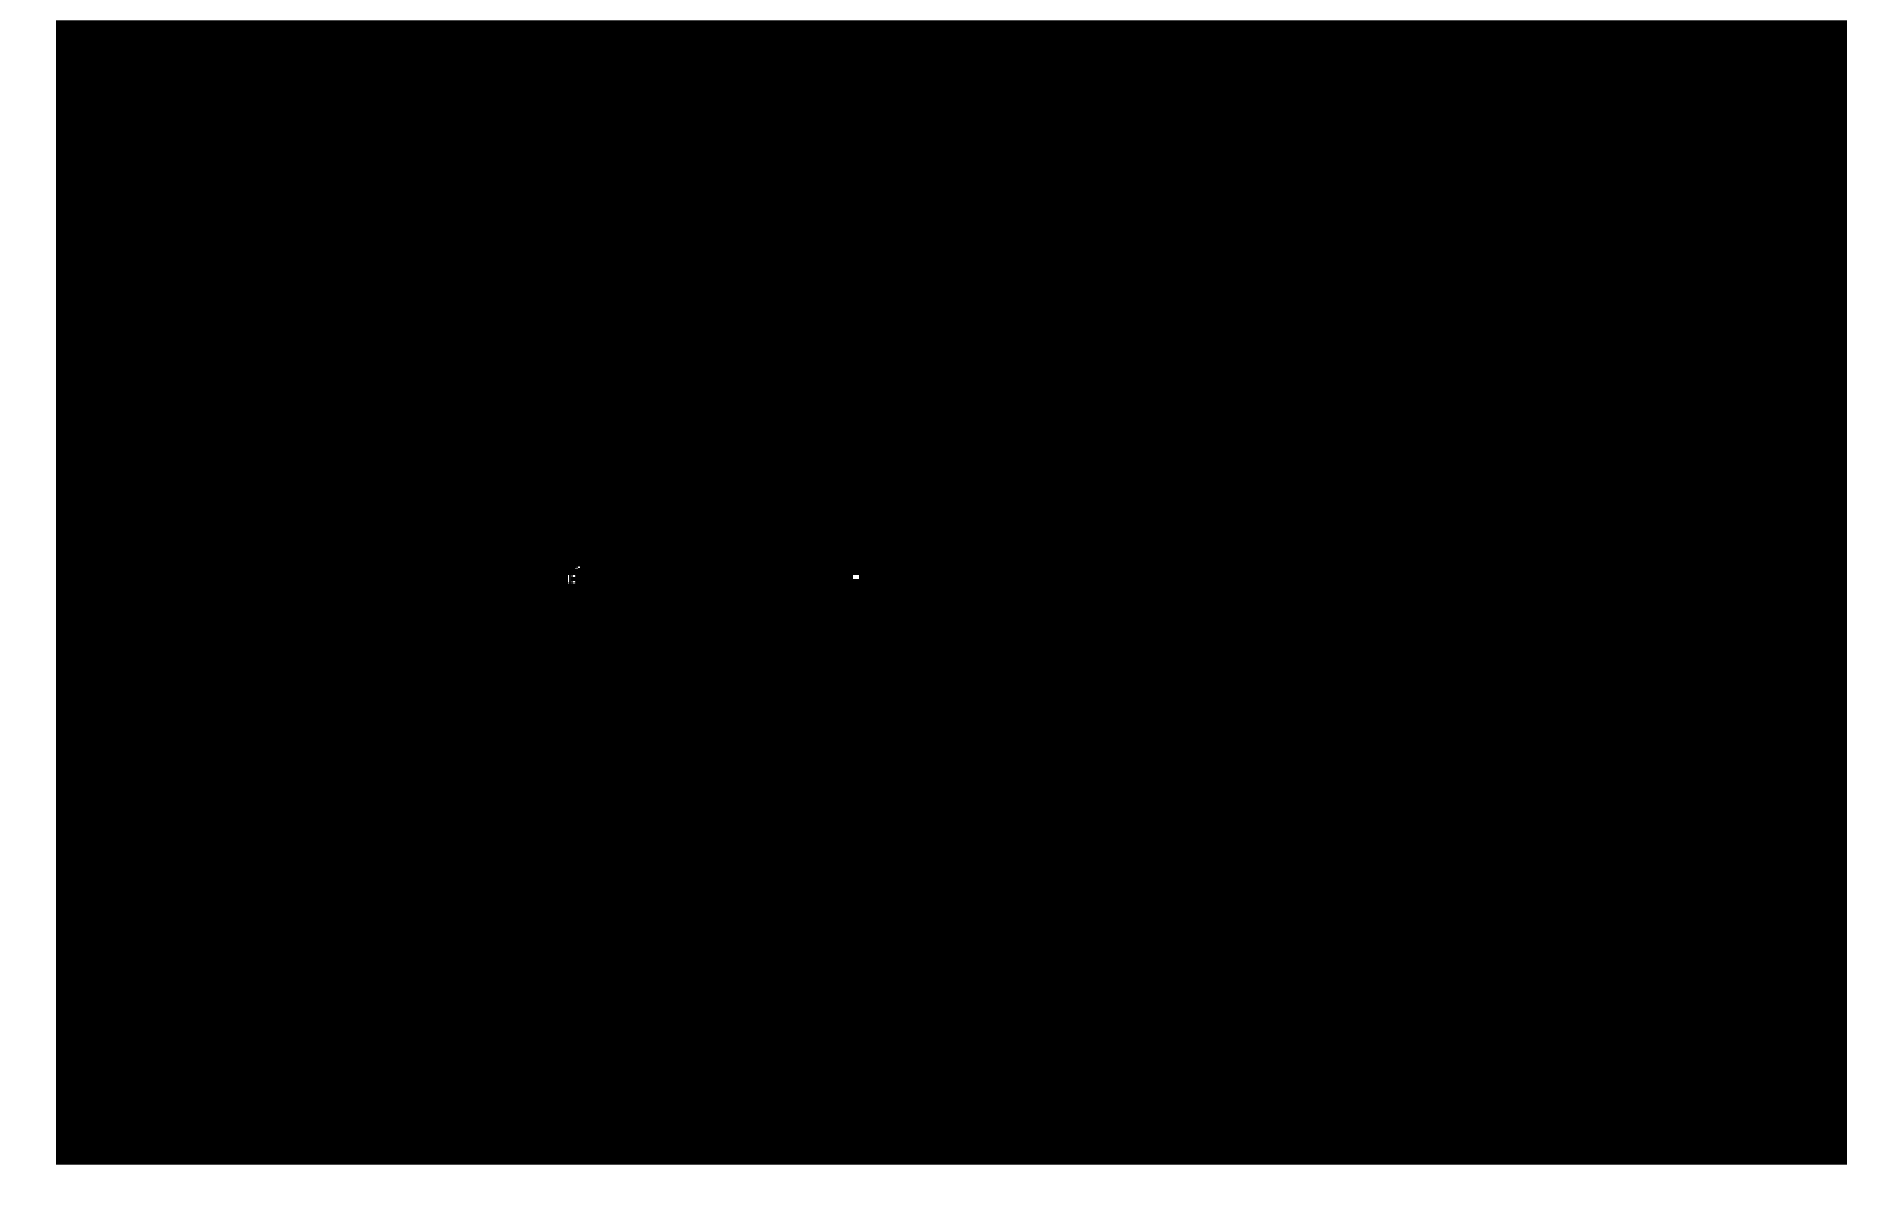

clc;
clear all;
close all;
%image = imread("TennisBallTest.jpeg");
image_orig = imread("test.png");
imshow(image_orig);

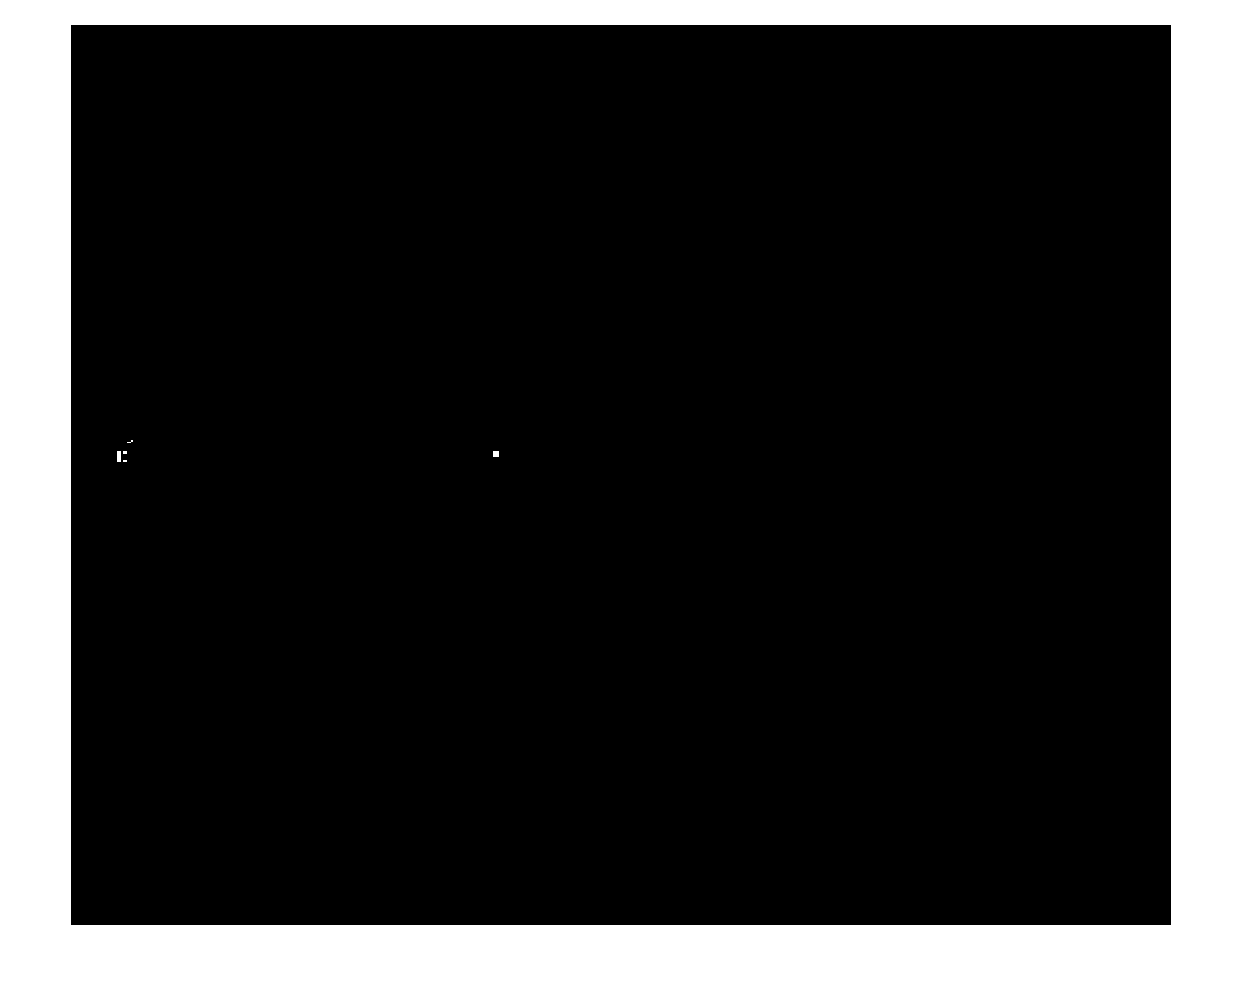

targetSize = [900,1100];
r = centerCropWindow2d(size(image_orig),targetSize); 
image_rgb = imcrop(image_orig,r);
image = image_rgb(:,:,1) > 0; % normalized by 255
imshow(image);

% grayImage = rgb2gray(image);
% [edges, thresh] = edge(grayImage, 'sobel');
% [W, H] = size(edges)
% grayImage = rgb2gray(image);
% [edges, thresh] = edge(grayImage, 'sobel');

[W, H] = deal(900, 1100)

W = 900

H = 1100

% Initialize V_x
V_x = zeros(1, W);

F = fimath('OverflowAction','Saturate', ...
            'RoundingMethod','Nearest', ...
            'MaxProductWordLength',9);

for j = 1:W-1
    for k = j+1:W
        for i = 1:H

            % value = fi((j+k)/2,F); %  fi - fixed point
            % index = value.int16;
            index = floor((j+k)/2);
            % index = max(min(index, W), 1);
            % if index >  W
            %     index = W;
            % end

            V_x(index) = V_x(index) + image(j, i) * image(k,i);
        end
    end
end

ans = 1

ans = 2

ans = 3

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 22

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28

ans = 29

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 19

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28

ans = 29

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 44

ans = 45

ans = 19

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28

ans = 29

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 22

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28

ans = 29

ans = 30

ans = 31

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 44

ans = 45

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28

ans = 29

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 37

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 35

ans = 36

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 1

ans = 2

ans = 3

ans = 44

ans = 45

ans = 46

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 26

ans = 27

ans = 28

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 1

ans = 2

ans = 3

ans = 16

ans = 17

ans = 18

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

% Initialize V_y
V_y = zeros(1, H);

for j = 1:H-1
    for k = j+1:H
        for i = 1:W
            % value = fi((j+k)/2,F);
            % index = value.int16;
            index = floor((j+k)/2);
            if index > H
                index = H; % Ensure index does not exceed H
            end
            V_y(index) = V_y(index) + image(i, j) * image(i, k);
        end
    end
end

% Find local maxima in V_x and V_y
local_maxima_x = islocalmax(V_x);
local_maxima_y = islocalmax(V_y);

f = 1;

% Initialize Vr
% Vr = zeros(W, H, 7); % Adjust the third dimension based on the maximum possible radius
Vr = zeros(1,7);

for i = 1:W % columns
    if local_maxima_x(i)
        for j = 1:H % rows
            if local_maxima_y(j)
                for k = 1:H % rows
                    for m = 1:W % columns 
                        if image(m,k) % Check if there's an edge at (k, m)
                            r = round(norm([m, k] - [j, i])); % Calculate the distance and round to the nearest integer
                            % Vr(j, i, r) = Vr(j, i, r) + 1; % Increment the vote for the circle centered at (i, j) with radius r
                            if r <= 7
                                Vr(r) = Vr(r) + 1;
                            end
                        end
                    end
                end
                % Check if the maximum value in Vr(i, j, :) is greater than f * 4 * sqrt(r)
                % [max_val, max_r] = max(squeeze(Vr(j, i, :)));
                % if max_val > f * 4 * sqrt(max_r)
                %     % (i, j) with radius max_r is considered a circle
                %     fprintf('Circle detected at (%d, %d) with radius %d\n', j, i, max_r);
                % end
            end
        end
    end
end
print("bla");